Analyze the results

Plot chart animation

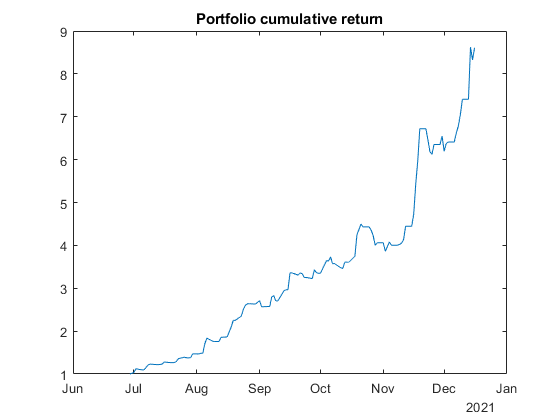

% Plot animated chart with pause or drawnow function
% Plot portCumRetTT    

OSTportDailyRet     = sum(OSTnetDailyRetperSymTT.Variables,2) ;
OSTportDailyRetTT   = timetable(OSTportDailyRet, 'RowTimes', OSTnetDailyRetperSymTT.Time, 'VariableNames', "OSTportDailyRet") ;
OSTportCumRetTT     = ret2tick (OSTportDailyRetTT) ;

for walk_i = 1:nWalk
%     i = 2
%     walk_i = walk_i 

    walkStart_i = 1+ nstepOST*(walk_i-1);
    walkEnd_i = walkStart_i + nstepOST-1;
    OSTportCumRetTT_i = OSTportCumRetTT(1:walkEnd_i-1, :);
    
%     semilogy(OSTportCumRetTT_i.Time, OSTportCumRetTT_i.Variables)
    plot(OSTportCumRetTT_i.Time, OSTportCumRetTT_i.Variables)
    title ("Portfolio cumulative return")
    
    drawnow 
    pause(2);

end

Plot the equity curve on OST dataset

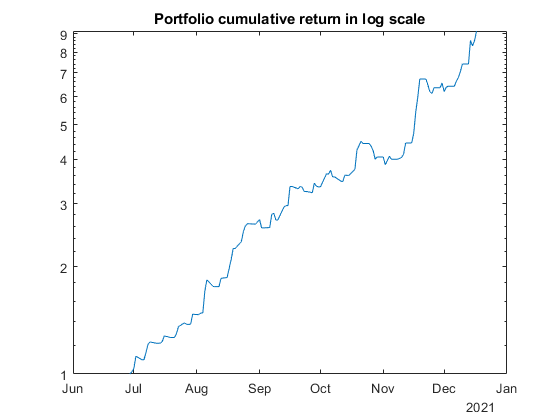

OSTportDailyRet     = sum(OSTnetDailyRetperSymTT.Variables,2) ;
OSTportDailyRetTT   = timetable(OSTportDailyRet, 'RowTimes', OSTnetDailyRetperSymTT.Time, 'VariableNames', "OSTportDailyRet") ;
OSTportCumRetTT     = ret2tick (OSTportDailyRetTT) ;
semilogy(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
title ("Portfolio cumulative return in log scale")

Statistics

% OSTportCumRetTT = ret2tick (OSTportDailyRetTT) ;
% 
% plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)

% CAGR
timeVar = OSTportCumRetTT.Time ;
OSTportCumRet = OSTportCumRetTT.Variables ;
OSTportCumRetEnd = OSTportCumRet(end,:)

OSTportCumRetEnd = 9.1642

nYear = yearfrac (timeVar(1,:), timeVar(end,:))

nYear = 0.4685

CAGR = ((OSTportCumRet (end,:) / OSTportCumRet (1,:))^(1/nYear)) - 1

CAGR = 112.1330

MonthlyRet = (1+CAGR)^(1/12) - 1

MonthlyRet = 0.4830


% Drawdown
[MDD,MaxDDIndex] = maxdrawdown(OSTportCumRetTT.Variables) ;
MaxDD = MDD 

MaxDD = 0.1413

drawDownTime = timeVar(MaxDDIndex)

drawDownTime = 2×1 datetime array
   21-Oct-2021
   02-Nov-2021


%% Transaction costs
% dailyTradingCostsPct = sum(tradingCostsTT.Variables,2) % tradingCostsTT can be extracted from tradingBacktestEngine
% dailyTradingCostsX = dailyTradingCostsPct .* OSTportCumRet
% tradingCostsTotalX = sum (dailyTradingCostsX) % tradingCosts as x of initial investment value

%% Slipage costs
% dailySlipageCostsPct = sum(slipageCostsTT.Variables,2) % slipageCostsTT can be extracted from tradingBacktestEngine
% dailySlipageCostsX = dailySlipageCostsPct .* OSTportCumRet
% slipageCostsTotalX = sum (dailySlipageCostsX) % slipageCosts as x of initial investment value


Number signal daily

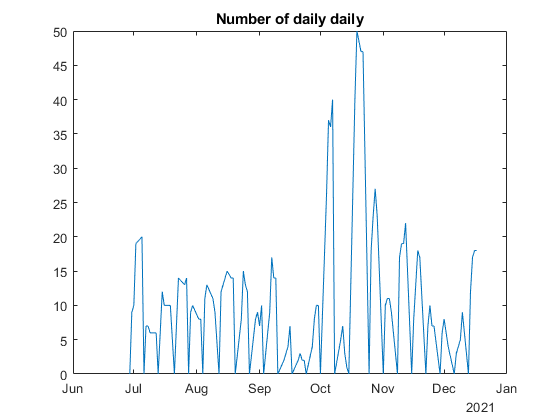

tradingSignal = (OSTnetDailyRetperSymTT.Variables > 0) + (OSTnetDailyRetperSymTT.Variables < 0) ;
nDailySignal = sum (tradingSignal,2) ;
nDailySignalTT = OSTportCumRetTT ;
nDailySignalTT.Variables = nDailySignal ;
nDailySignalTT.Properties.VariableNames = "nDailySignal" ;

% plot daily signal
plot(nDailySignalTT.Time , nDailySignalTT.Variables )
title("Number of daily daily")

Rank symbol based on cumulative return

symRank = rankSymbolsFcn (OSTnetDailyRetperSymTT);

headtitle = "Highest cumulative return"

ans = 8×2 table
     symbol     Cumulative Return
    ________    _________________

    {'REAL'}       {[1.2008]}    
    {'IATA'}       {[1.1810]}    
    {'LPIN'}       {[1.1520]}    
    {'DFAM'}       {[1.1271]}    
    {'BBYB'}       {[1.1251]}    
    {'SUPR'}       {[1.1218]}    
    {'MITI'}       {[1.1216]}    
    {'UVCR'}       {[1.1176]}    


headtitle = "Lowest cumulative return"

ans = 8×2 table
     symbol     Cumulative Return
    ________    _________________

    {'DEFI'}       {[0.9728]}    
    {'JMAS'}       {[0.9728]}    
    {'ESSA'}       {[0.9726]}    
    {'HEXA'}       {[0.9715]}    
    {'ERAA'}       {[0.9681]}    
    {'KBAG'}       {[0.9679]}    
    {'WIKA'}       {[0.9663]}    
    {'MLPL'}       {[0.9529]}    


Symbol return sample

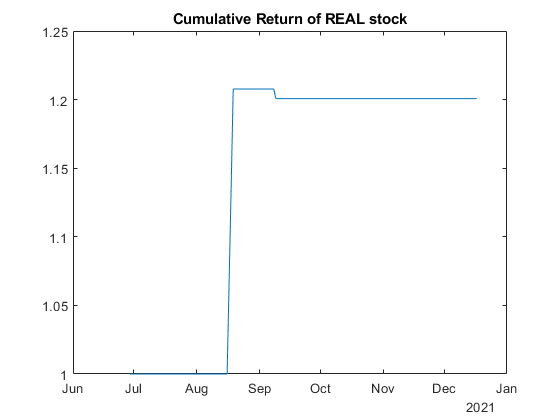

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.REAL)
title("Cumulative Return of REAL stock")

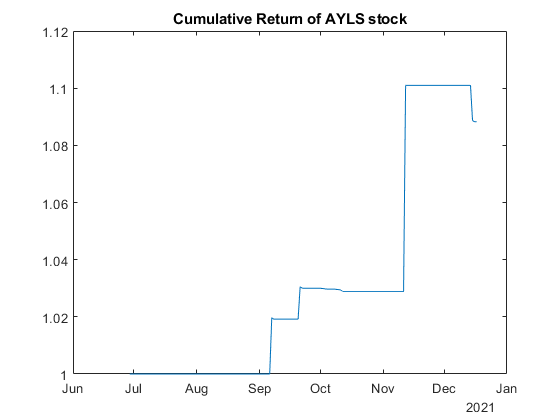

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.AYLS)
title("Cumulative Return of AYLS stock")

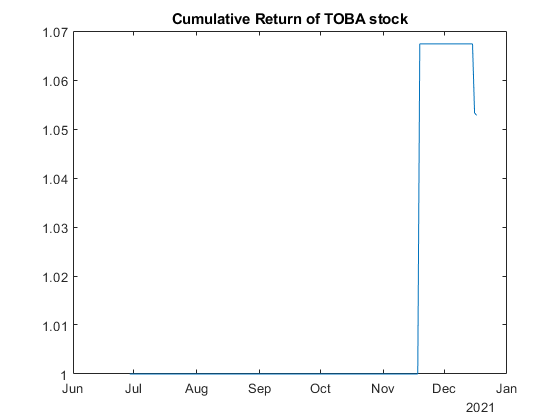

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.TOBA)
title("Cumulative Return of TOBA stock")

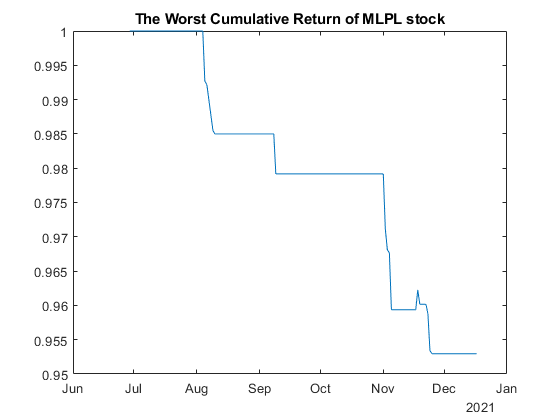

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.MLPL)
title("The Worst Cumulative Return of MLPL stock")